clc
clear
close all

## parameters

% load ss
load('Assignment_Data_SC42145.mat');

% operational parameters
P_rated = 1.8E6; % W
T_rated = 1E4; % Nm
W_rated = 180; % rad/s
V_lin = 16; % m/s

## SISO controller

SISO_ss = FWT(1,1); % Beta to Omega
figure(1);
subplot(1,2,1); margin(SISO_ss)
[gain_margin,phase_margin,w_crossover_g,w_crossover_p] = margin(SISO_ss)

gain_margin = 5.2828

phase_margin = Inf

w_crossover_g = 0

w_crossover_p = NaN

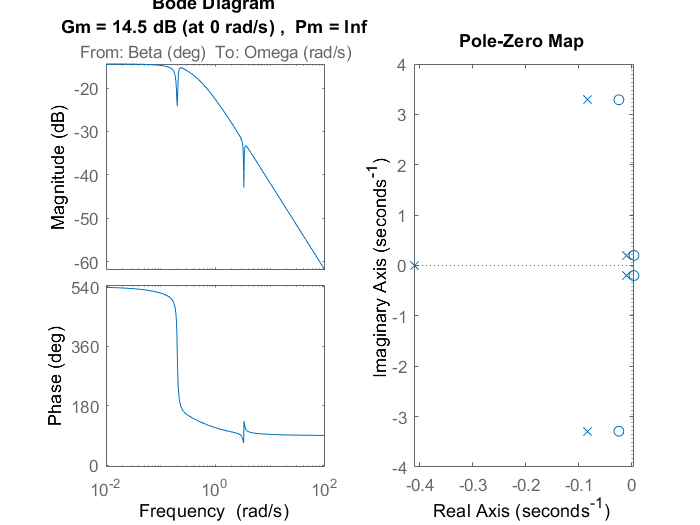


subplot(1,2,2); pzmap(SISO_ss);

poles = pole(SISO_ss)

poles =   -0.0832 + 3.2936i
  -0.0832 - 3.2936i
  -0.4104 + 0.0000i
  -0.0106 + 0.2022i
  -0.0106 - 0.2022i


zeros_ = zero(SISO_ss)

zeros_ =    0.0038 + 0.2000i
   0.0038 - 0.2000i
  -0.0246 + 3.2897i
  -0.0246 - 3.2897i


tf(SISO_ss)

ans =
 
  From input "Beta (deg)" to output "Omega (rad/s)":
  -0.07988 s^4 - 0.003315 s^3 - 0.8677 s^2 + 0.006493 s - 0.03458
  ---------------------------------------------------------------
   s^5 + 0.5979 s^4 + 10.98 s^3 + 4.709 s^2 + 0.5421 s + 0.1827
 
Name: V = 14 m/s
Continuous-time transfer function.




SISO_ss

SISO_ss =
 
  A = 
                 Omega (rad/s   z1dot (m/s)        z1 (m)   z2dot (m/s)        z2 (m)
   Omega (rad/s        -0.422       -0.2204             0       -0.2204             0
   z1dot (m/s)        0.02328      -0.01085         -0.04     -0.009574             0
   z1 (m)                   0             1             0             0             0
   z2dot (m/s)         0.1455      -0.05984             0       -0.1651        -10.82
   z2 (m)                   0             0             0             1             0
 
  B = 
                 Beta (deg)
   Omega (rad/s    -0.07988
   z1dot (m/s)    -0.006722
   z1 (m)                 0
   z2dot (m/s)     -0.04202
   z2 (m)                 0
 
  C = 
                 Omega (rad/s   z1dot (m/s)        z1 (m)   z2dot (m/s)        z2 (m)
   Omega (rad/s             1             0             0             0             0
 
  D = 
                 Beta (deg)
   Omega (rad/s           0
 
Name: V = 14 m/s
Continuous-time state-s

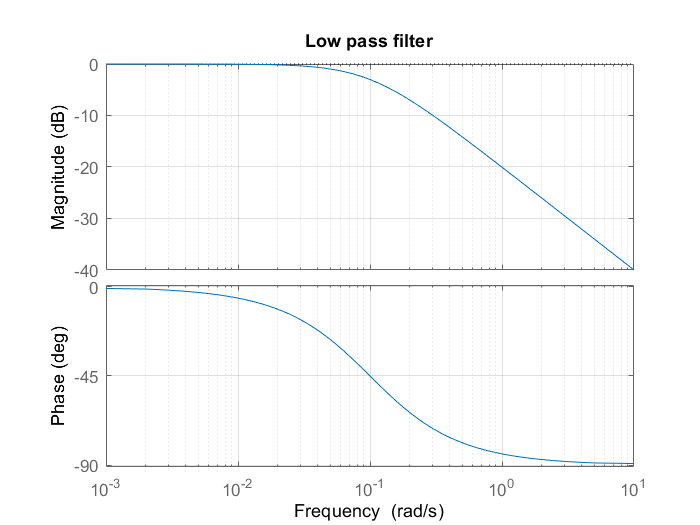


t = linspace(0,200,1000);
input= ones(1, length(t)); %reference

om_filter = 0.1;
low_pass_filter = tf([1],[1/om_filter, 1]); %first order low pass
%low_pass_filter = tf([1],[1]); %first order low pass

figure()
margin(low_pass_filter)
title('Low pass filter')
grid on


controller = pid(-0.1, -0.13 ,-0.2);  
%all negative as the rotational speed is negatively correlated with the
%rotational speed around the linearization point

lead_lag = tf([1e20 1], [1e10 1]);
lead_lag = tf([1], [1]);

% figure()
% margin(lead_lag)
% title('Lead lag')
% grid on

controller = lead_lag*controller;


closed_loop = inv(1+SISO_ss*controller*low_pass_filter)*SISO_ss*controller*low_pass_filter; %feedback

open_loop = SISO_ss*controller*low_pass_filter;

closed_loop = feedback(open_loop, 1);

bodeplot(closed_loop)

sensitivity = 1/(1+controller*SISO_ss);

[gain_margin,phase_margin,w_crossover_g,w_crossover_p] = margin(open_loop)

gain_margin = 14.6679

phase_margin = 73.3038

w_crossover_g = 0.1609

w_crossover_p = 0.0239

title('open loop')

%margin(sensitivity)
%title('sensitivity')

bandwidth_ = bandwidth(closed_loop)

bandwidth_ = 0.0341

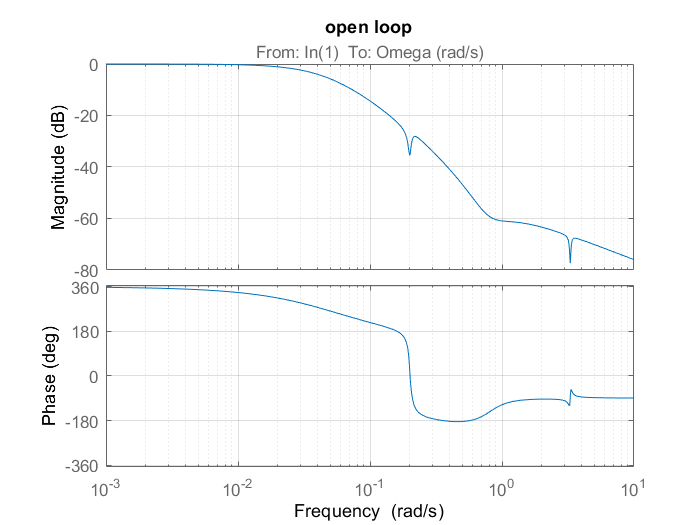

%pid(-4,0,0) gives about 0.1 Hz bandwidth --> good

grid on

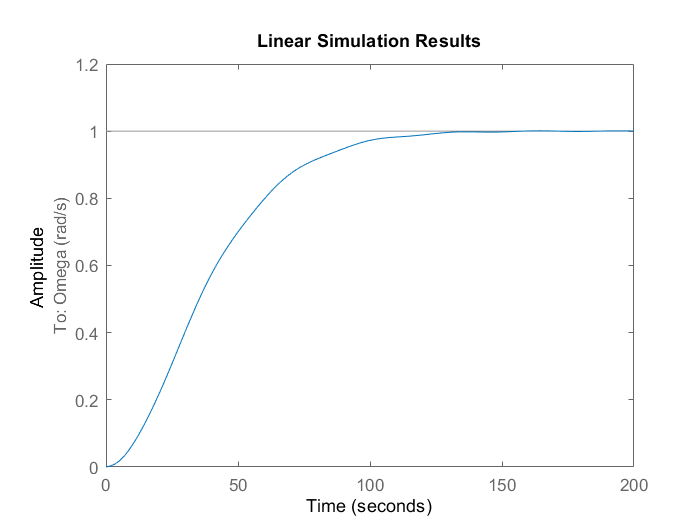

%title("Closed loop")

figure()
lsim(closed_loop, input, t)

info = stepinfo(closed_loop)

info = struct with fields:
        RiseTime: 62.6446
    SettlingTime: 106.0620
     SettlingMin: 0.9022
     SettlingMax: 1.0011
       Overshoot: 0.1058
      Undershoot: 0
            Peak: 1.0011
        PeakTime: 164.6229


G = FWT;
controller = [pid(-0., -0.265 ,-0.0), 0,0; 0,0,0];
closed_loop = feedback(G, -controller');

disturbance_v = zeros(size(t));
t_half = length(t)/4;
disturbance_v(t_half:end) = 1

disturbance_v =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


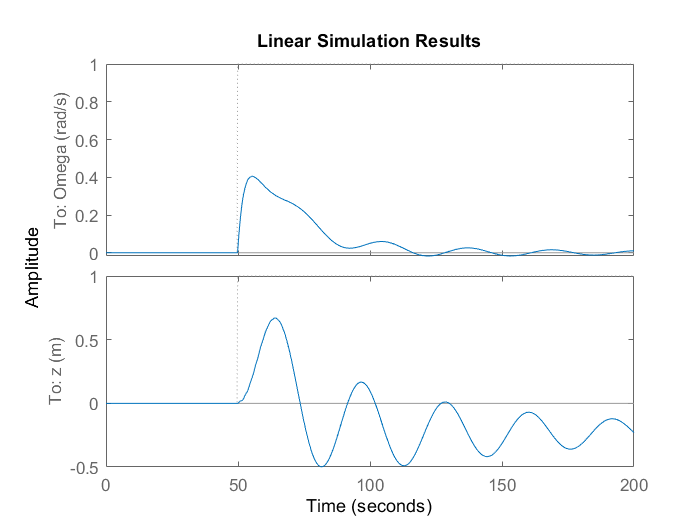

input = [zeros(size(t));zeros(size(t));disturbance_v];
lsim(closed_loop, input, t)

G = tf(FWT(1:2,1:2));
RGA = G.*inv(G)

RGA =
 
  From input 1 to output...
                                                          
       -0.2766 s^11 - 0.1812 s^10 - 6.472 s^9 - 3.567 s^8 
                                                          
               - 42.57 s^7 - 19.44 s^6 - 53.9 s^5         
                                                          
               - 22.57 s^4 - 4.414 s^3 - 1.704 s^2        
                                                          
                                     - 0.09321 s - 0.03341
                                                          
   1:  ---------------------------------------------------
                                                          
       s^12 + 1.212 s^11 + 23.86 s^10 + 24.72 s^9         
                                                          
               + 161.6 s^8 + 140.8 s^7 + 230.2 s^6        
                                                          
               + 169.1 s^5 + 54.54 s^4 + 14.15 s^3        
                    

[U,S,V] = svd(evalfr(RGA, 0))

U =    -0.0317    0.9995
    0.9995    0.0317


S =    20.8109         0
         0    0.1110


V =     0.9995    0.0317
   -0.0317    0.9995



max_sigma_0 = max(diag(S))

max_sigma_0 = 20.8109

min_sigma_0 = min(diag(S))

min_sigma_0 = 0.1110

gamma_0 = max_sigma_0/min_sigma_0

gamma_0 = 187.4193


[U,S,V] = svd(evalfr(RGA, 0.8*pi))

U =    -0.2649    0.9643
    0.9643    0.2649


S =     1.2823         0
         0    0.9230


V =     0.9643    0.2649
   -0.2649    0.9643


max_sigma_04Hz = max(diag(S))

max_sigma_04Hz = 1.2823

min_sigma_04Hz = min(diag(S))

min_sigma_04Hz = 0.9230

gamma_04Hz = max_sigma_04Hz/min_sigma_04Hz

gamma_04Hz = 1.3892


poles = pole(FWT)

poles =   -0.0832 + 3.2936i
  -0.0832 - 3.2936i
  -0.4104 + 0.0000i
  -0.0106 + 0.2022i
  -0.0106 - 0.2022i


zeros_ = zero(FWT)

zeros_ =   -0.0078 + 1.2358i
  -0.0078 - 1.2358i


[K,CL,GAM,INFO] = hinfsyn(P,1,1); % Hinf design
